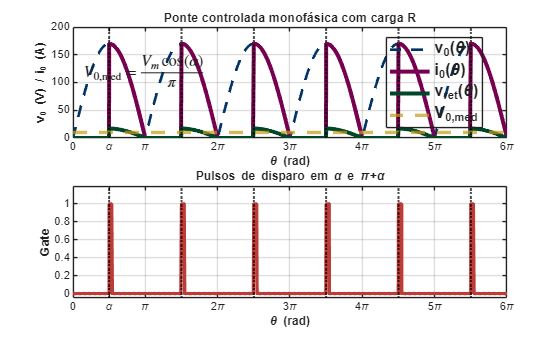

%% Retificador monofásico ONDA COMPLETA (ponte CONTROLADA) + carga R

clear; clc; close all;

Vm      = 170;
R       = 10;
alpha_d = 90;
ncy     = 3;
Ns      = 200000;
pw_d    = 8;
A_gate  = 1;

alpha = deg2rad(alpha_d);
pw    = deg2rad(pw_d);

theta = linspace(0, 2*pi*ncy, Ns);

v_s = Vm*sin(theta);

phi  = mod(theta, pi);
cond = (phi >= alpha) & (phi <= pi);
v0   = abs(v_s) .* cond;
i0   = v0 / R;

Vmed = 10;

Np = 2*ncy;
theta_fire = alpha + (0:(Np-1))*pi;

gate = zeros(size(theta));
for k = 1:numel(theta_fire)
    gate = gate + A_gate * (theta >= theta_fire(k) & theta <= (theta_fire(k) + pw));
end

statale.maincolor = [0   51  102]/255;
statale.lilla     = [120 0   80 ]/255;
statale.darkgreen = [0   70  40 ]/255;
statale.red       = [190 60  55 ]/255;
statale.yellow    = [200 155 20 ]/255;

LW = 3.0;

figure('Color','w');
v_ret = abs(v_s);

ax1 = subplot(2,1,1);
plot(theta, v_ret, '--', 'LineWidth', 2, 'Color', statale.maincolor); hold on;
plot(theta, v0, 'LineWidth', LW, 'Color', statale.lilla);
plot(theta, i0, 'LineWidth', LW, 'Color', statale.darkgreen);
hmed = yline(Vmed, '--', 'LineWidth', 2.5);
hmed.Color = statale.yellow;
grid on;

title('Ponte controlada monofásica com carga R');
ylabel('v_0 (V) / i_0 (A)');
xlabel('\theta (rad)');

txt = '$V_{0,\mathrm{med}}=\frac{V_m\cos(\alpha)}{\pi}$';
text(0.02*(theta(end)-theta(1)), 0.92*max(v0+eps), txt, ...
    'Interpreter','latex', 'FontWeight','bold', 'FontSize', 12, ...
    'VerticalAlignment','top');

for k = 1:numel(theta_fire)
    xline(theta_fire(k), ':k', 'LineWidth', 1.5);
end

lgd = legend('v_0(\theta)','i_0(\theta)','v_{ret}(\theta)','V_{0,med}','Location','best');
lgd.FontSize   = 12;
lgd.FontWeight = 'bold';
lgd.Color      = 'none';

ax1.XLabel.FontWeight = 'bold';
ax1.YLabel.FontWeight = 'bold';

ax2 = subplot(2,1,2);
plot(theta, gate, 'LineWidth', 2.5, 'Color', statale.red); hold on;
grid on;

ylim([-0.05 1.2*A_gate]);
ylabel('Gate');
xlabel('\theta (rad)');
title('Pulsos de disparo em \alpha e \pi+\alpha');

for k = 1:numel(theta_fire)
    xline(theta_fire(k), ':k', 'LineWidth', 1.5);
end

ax2.XLabel.FontWeight = 'bold';
ax2.YLabel.FontWeight = 'bold';

linkaxes([ax1 ax2],'x');

k2 = floor(theta(end)/pi);
xt = (0:k2)*pi;
set([ax1 ax2], 'XLim', [0 theta(end)], 'XTick', xt);

labs = strings(size(xt));
for kk = 1:numel(xt)
    m = xt(kk)/pi;
    if abs(m - 0) < 1e-12
        labs(kk) = "0";
    elseif abs(m - 1) < 1e-12
        labs(kk) = "\pi";
    else
        labs(kk) = sprintf('%g\\pi', m);
    end
end
set([ax1 ax2], 'XTickLabel', labs);

xt = unique(sort([xt alpha]));
set([ax1 ax2], 'XTick', xt);

labs = strings(size(xt));
for kk = 1:numel(xt)
    if abs(xt(kk) - alpha) < 1e-12
        labs(kk) = "\alpha";
    else
        m = xt(kk)/pi;
        if abs(m - 0) < 1e-12
            labs(kk) = "0";
        elseif abs(m - 1) < 1e-12
            labs(kk) = "\pi";
        else
            labs(kk) = sprintf('%g\\pi', m);
        end
    end
end
set([ax1 ax2], 'XTickLabel', labs);